# DifferentialEquations.mlx

 This script illustrates numerical and symbolic methods of solution of systems of differential equations in MATLAB to model physical processes. The initial focus is on ballistic trajectories with aerodynamic drag force linear in velocity, a model that can be checked analytically. A slight modification will allows numerical solution for ballistic motion with a more realistic drag for model that is quadratic in speed.

A nonlinear predator-prey model is used to illustrate how to solve a pair of coupled differential equations. This model exhibits very interesting behavior. The method of solution can be used to model ballistic trajectories and other physical phenomena in three dimensions.

Author: Duncan Carlsmith

## Euler method of integration

Suppose we have a  point-like falling mass m subject to a uniform gravitational field and a drag force of the form $f_{drag} = -bv$ where $v$ is the velocity and $b$ is some air and mass dependent constant. With coordinate $z$ and velocity $v$ downward, for 1-dimensional motion, Newton's 2nd law has the form

 $ma= F => m dv/dt= mg-bv$ or 


$$a(t)=dv/dt = g-  v/\tau$$


with a time constant $\tau = m/b$ . Given $v(t)$, we can write the approximate relationship


$$dv=v(t+dt)-v(t)= a(v(t),t)dt$$


so find (approximately) the velocity at a slightly later (or earlier) time, given the velocity $v(t)$  at time $t$, using


$$v(t+dt)=v(t)+a(t)dt$$


with acceleration $a(t) = g-v(t)/\tau$. Starting with some initial $v(0$), we can find the velocity as a function of time for a sequence of time increments by iteration. Having found the velocity as a function of time, we can write


$$z(t+dt) =z(t)+ v(t)dt$$


and so, given some initial value $z(0)$,we can iterate to find the coordinate $z$ as a function of time. Let's do this.

delete(findall(0,'Type','figure'))% close all open figure windows

Loop over a choice of number of steps `N` in the time range, i.e. try various dt's to see how the results depend on the size of the choice.

for N=10:20:100% compare 10,30,50,70,90 steps

Inside this loop, we will numerically step the mass through a trajectory, computing and updating the velocity and position along the way, and after we are done, plot the results.

Declare global variables common to the main code to share with a function given below. We initialize them here and could change the values globally. FYI, passing all values through arguments not via global variables is a preferred practice.

global g tau;

Pick an illustrative  $\tau=$3 sec time constant and a 5 second time window for the calculation. Since $\tau$ is the characteristic time for the speed to approach terminal speed, with these values, there should be a significant drag effect.

g=10.0;tau = 3.0;   % acceleration of gravity and time constant (SI units)
tmin = 0; tmax = 5; % a range of times

Set initial conditions for the calculation. Let's just drop the mass from rest. Change these values if you want to.

v0=0.0;z0=0.0;% initial velocity and position

Prepare a fixed vector of discrete times and initialize cooresponding vectors of values for acceleration, velocity, and position. The preallocation is not essential but saves computation times as MATLAB doesn't have to keep extending and extending the vectors.

t=linspace(tmin,tmax, N);% make a vector of time values
dt=t(2)-t(1);% time increment
a= zeros(1,numel(t));% preallocate vector of acceleration values
v= zeros(1,numel(t));% preallocate vector of velocity values
z= zeros(1,numel(t));% preallocate vector of position values
a(1)= g;%initialize
v(1)=v0;%initialize
z(1)=z0;%initialize

This inner loop steps through the time window predicting values at the end of each interval from values at the beginning of each interval, i.e. from values in the preceding interval.

for i=2:N
    %Acceleration function 'accel' at end of script will be used
    a(i)= v_t(t(i-1),v(i-1)); 
    v(i)= v(i-1)+a(i-1)*dt;
    z(i)= z(i-1)+v(i-1)*dt+(1/2)*a(i-1)*dt^2; % why not be a bit more precise...
end

We are done tracking the mass. Plot position, velocity, and acceleration versus time including a symbol so we can see the time steps.

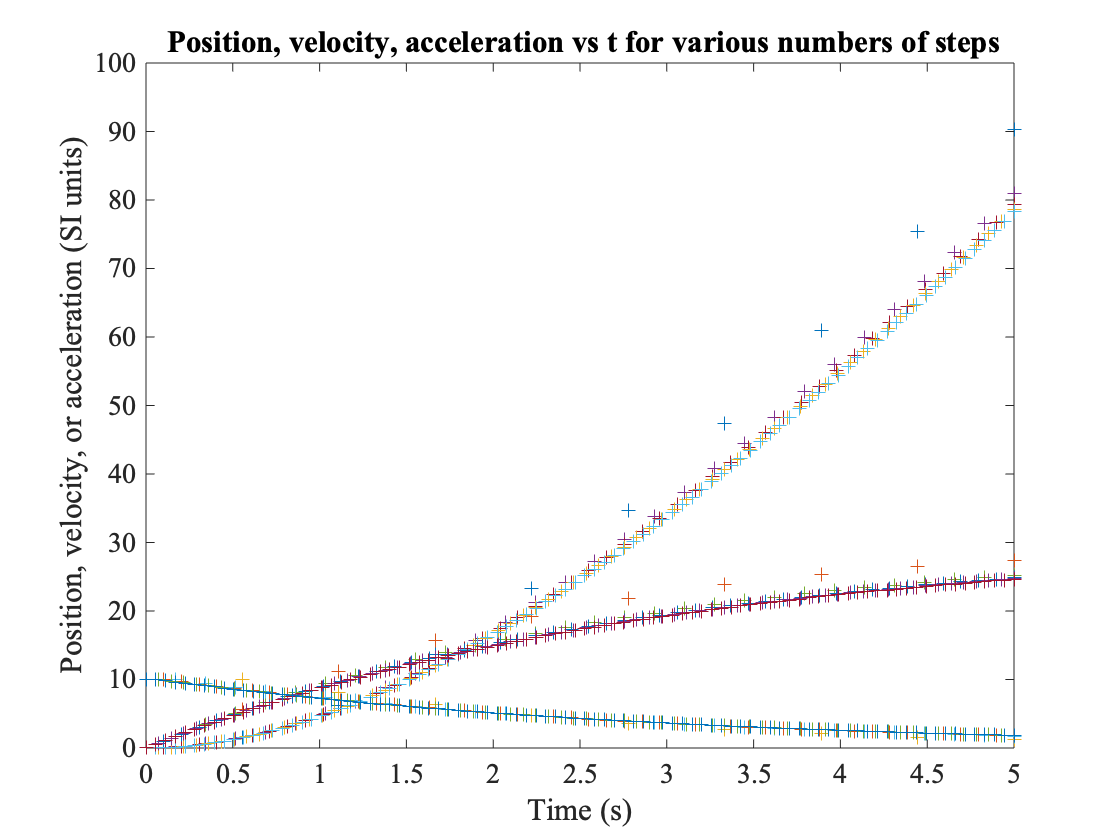

plot(t,z,'+')
xlabel('Time (s)')
ylabel('Position, velocity, or acceleration (SI units)')
hold on
plot(t,v,'+')
plot(t,a,'+')
% End of the loop over number of steps N
end
title(' Position, velocity, acceleration vs t for various numbers of steps')

Note that the acceleration starts at g and decays to zero as terminal speed is approached. The speed increases linearly with time at first, and then plateaus at the terminal speed. The displacement grows quadrattically with time at first but is ultimately linear in time. Check out the plot to see how more steps changes the answers. As the number of steps increases, the numerical values converge at each point in time for each variable z, v, and a. You may have to zoom in on the plot.

## Symbolic and analytic solutions

The solution to the problem just posed can be found analytically by integrating both sides of the expression for acceleration thusly:

${dv\over dt} = g-v/\tau \rightarrow \int {dv\over (g-v/\tau)}=\int dt \rightarrow \ln {{g-v(t)/\tau}\over {g-v_0/\tau}}=t\rightarrow  v(t) = g \tau (1-e^{-t/\tau}) - v_0e^{-t/\tau})$.

The velocity approaches terminal velocity $g\tau$ exponentially (first term) while the dependence on the initial velocity $v_0$ is erased exponentially (2nd term). MATLAB can also do this: (See help for ["solve differential equation"](https://www.mathworks.com/help/symbolic/solve-a-single-differential-equation.html) and [`"dsolve"`](https://www.mathworks.com/help/symbolic/dsolve.html) and [documentation on Symbolic Math Toolbox](https://www.mathworks.com/help/releases/R2019b/pdf_doc/symbolic/index.html?s_cid=doc_ftr) for further information.) 

MATLAB can work with symbolic variables with no preassigned values. Declare some symbolic functions and variables that we will need. To distinguish these symbolic things from numerical ones in this script, we use capital letters here (not necessary, just convenient).

syms Z(T) V(T) TAU G V0 Z0

We declare a first order differential equation $dv/dt = g-v/\tau$ (hat we will call `ode)` using [diff](https://www.mathworks.com/help/symbolic/diff.html) thusly:

ode = diff(V,T)==G - V/TAU;

We declare a constraint, called `cond`, that the initial velocity is a prenamed symbolic variable. Otherwise the solution will have an equivalent arbitrary constant of integration called something opaque like "C2".  Comment out the following line and remove the "`,cond`" in the argument of `dsolve `below to verify this.

cond = V(0) == V0;

The following function call creates a function we have simply called `vSolution`(T) (pick any convenient name) which is the symbolic solution for velocity. Since there is no semicolon, after the call, MATLAB will print out the function. 

vSolution(T) = dsolve(ode,cond)

$$vSolution(T) = {\mathrm{e}}^{-\frac{T}{\mathrm{TAU}}}\,\left(V_{0}-G\,\mathrm{TAU}\right)+G\,\mathrm{TAU}$$

The result should be that obtained by the integration we were able to do by hand above.

Since position is related to velocity by  $dz/dt = v(t)$, we can integrate again analytically by hand (or use dsolve) to get position versus time:

$z(t) =  z_0 + \tau (v_0 - g\tau) + gt\tau -\tau e^{-t/\tau}(v_0 - g\tau)$.

Let's go ahead and try it with MATLABs symbolic solution methods.

ode = diff(Z,T)==vSolution(T)

$$ode(T) = \frac{\partial }{\partial T}Z\left(T\right)={\mathrm{e}}^{-\frac{T}{\mathrm{TAU}}}\,\left(V_{0}-G\,\mathrm{TAU}\right)+G\,\mathrm{TAU}$$

Constrain initial position now. Note, z0 was declared to be a symbolic variable above.

cond = Z(0) == Z0 

$$cond = Z\left(0\right)=Z_{0}$$

zSolution(T) = dsolve(ode, cond)

$$zSolution(T) = Z_{0}+\mathrm{TAU}\,\left(V_{0}-G\,\mathrm{TAU}\right)-\mathrm{TAU}\,{\mathrm{e}}^{-\frac{T}{\mathrm{TAU}}}\,\left(V_{0}-G\,\mathrm{TAU}\right)+G\,T\,\mathrm{TAU}$$

The result should be the position solution derived above.

Let's compute the values of the exact solutions. First substitute the numerical value of initial velocity v0 for the symbolic variable V0 into the symbolic function with [subs](https://www.mathworks.com/help/symbolic/subs.html) to get a new function vS.

vS= subs(vSolution, V0, v0)

$$vS(T) = G\,\mathrm{TAU}-G\,\mathrm{TAU}\,{\mathrm{e}}^{-\frac{T}{\mathrm{TAU}}}$$

and `subs` the numerical initial position z0 for the symbolic variable Z0 and so on, so our final vS depends only on symbolic time.

vS= subs(vS, Z0, z0);vS= subs(vS, TAU, tau);vS= subs(vS, G, g)

$$vS(T) = 30-30\,{\mathrm{e}}^{-\frac{T}{3}}$$

Superpose the exact solution for velocity on the plot generated above via numerical methods, using blue circles.

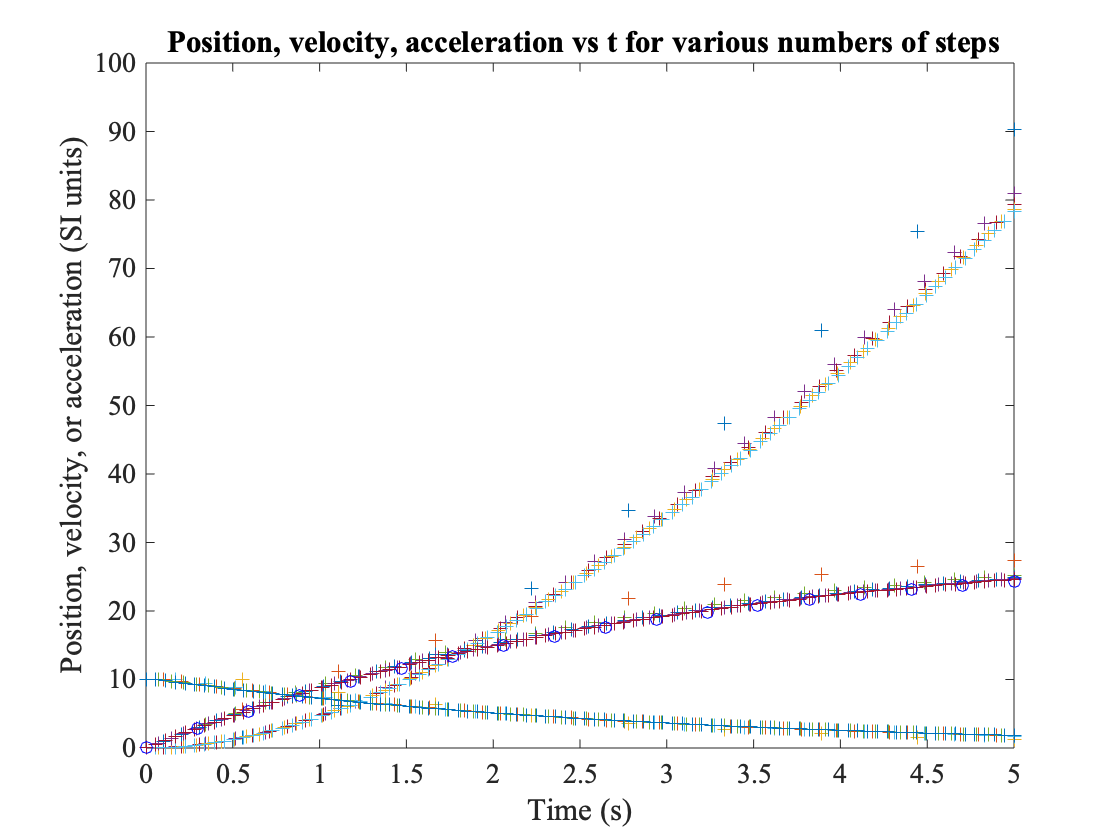

fplot(vS, [tmin tmax],'ob')

Open this plot in a new window and zoom in to examine differences between the exact and the numerical results for the velocity over time.

Add here code to superpose the exact solutions for position and for acceleration on the plot if you would like.

%%%%%

## Accurate solution of differential equations

The simple minded (Euler) method of numerical solution above uses a linear approximation to find a new value after a small time step dt. It can be made more accurate by, for each time step, using (and computing if needed) several values of the velocity and acceleration to more accurately extrapolate to the predicted value after a time step. MATLAB supplies an optimized numerical ordinary differential equation solver called [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html). It uses a "Dormand-Prince pair of Runge- Kutta formulas" and an adaptive step size that compares the results of 4th order and 5th order prediction methods. Adaptive here mean the algorithm takes small steps where needed and larger steps where sensible. No need to dig into the intricacies of the algorithm.

The next call uses an acceleration function and ode45 to integrate acceleration to find velocity.

ode45(@v_t,[tmin,tmax],v0)

The 1st argument passed to `ode45` is the function to integrate, the second the range for its independent variable, and the 3rd the initial value of the passed argument, the dependent variable in the ordinary differential equation. (See acceleration function below.) The call to `ode45` without catching output defaults to create a plot. To set integration tolerance, use [odeset](https://www.mathworks.com/help/matlab/ref/odeset.html).

You are used to calling MATLAB built-in functions. You can create your own functions and store them in your path for re-use by various codes. See MATLAB's [introduction to functions](https://www.mathworks.com/help/matlab/functions.html). ode45 is a generic differential equation solver. It needs the initial value for the dependent variables and the range of the independent variable and the relationship between the rates of change of the dependent variables and the values of the dependent and possibly independent variables. We supply these relationships via a function so must supply ode45 the name of the function to call. 

Zoom in on the velocity versus time plot to compare the exact result (blue circles) to the ode45 (line) result and observe that `ode45`  it is MUCH more accurate than the Euler method for the minimum time step used above.

We can get vectors of time values and associated velocity values resulting from our ode45 calculation by catching outputs with a call like

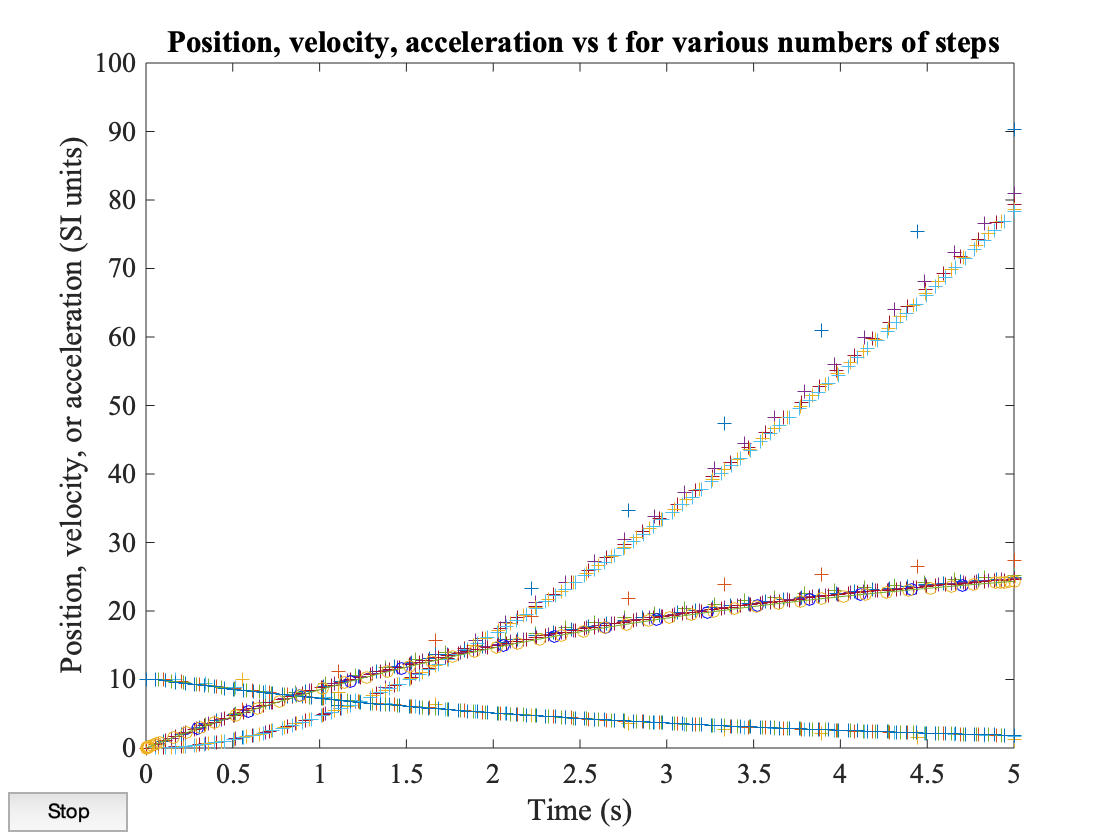

[Tode, Vode]=ode45(@v_t,[tmin,tmax],v0); 
plot(Tode,Vode)
hold off

Note the @ required handle and that ode45 wants the independent variable t=time and dependent variable v in that order and the function MUST respect this too. Even if it were a constant and didn't use the dependent variable it must pretend it will. Also, the funny bracket method of indicating the range of the independent variable must be used. 

## Lotka-Voltera model

We can use ode45 to solve a system of 1st order differential equations. Here is an example taken from [Physical Modeling in MATLAB, v 1.1.8 by Allen B. Downey](http://greenteapress.com/matlab/PhysModMatlab.pdf).

The Lotka-Voltera model describes the interactions between two species in an ecosystem, a predator and its prey, e.g. rabbits and foxes. The model is defined by the following system of differential equations: 


$$dR/dt =A(R,F,t)== aR(t)+bR(t)F(t)$$
 


$$dF/dt =B(R,F,t)== ebR(t)F(t) + cF(t)$$


where $R$ is the population of rabbits, $F$ is the population of foxes, $a$ is the natural growth rate of rabbits in the absence of predation, $c$ is the natural death rate of foxes in the absence of prey, $b$ is the death rate of rabbits per interaction with a fox, $e$ is the efficiency of turning eaten rabbits into foxes. The terms on the right-hand-side which define the functions $A$ and $B$ are nonlinear in the functions $R$ and $F$.

The function `lotka` below (appendix 2) takes a (column) 2-vector of arguments $V$ corresponding to $R$ and $F$ and returns the column vector of their derivatives with respect to time. Let's try `ode45` on this system as follows: 

Call `ode45` for 365 days and initially 100 rabbits and 10 foxes:

figure
ode45(@lotka, [0, 365], [100, 10])

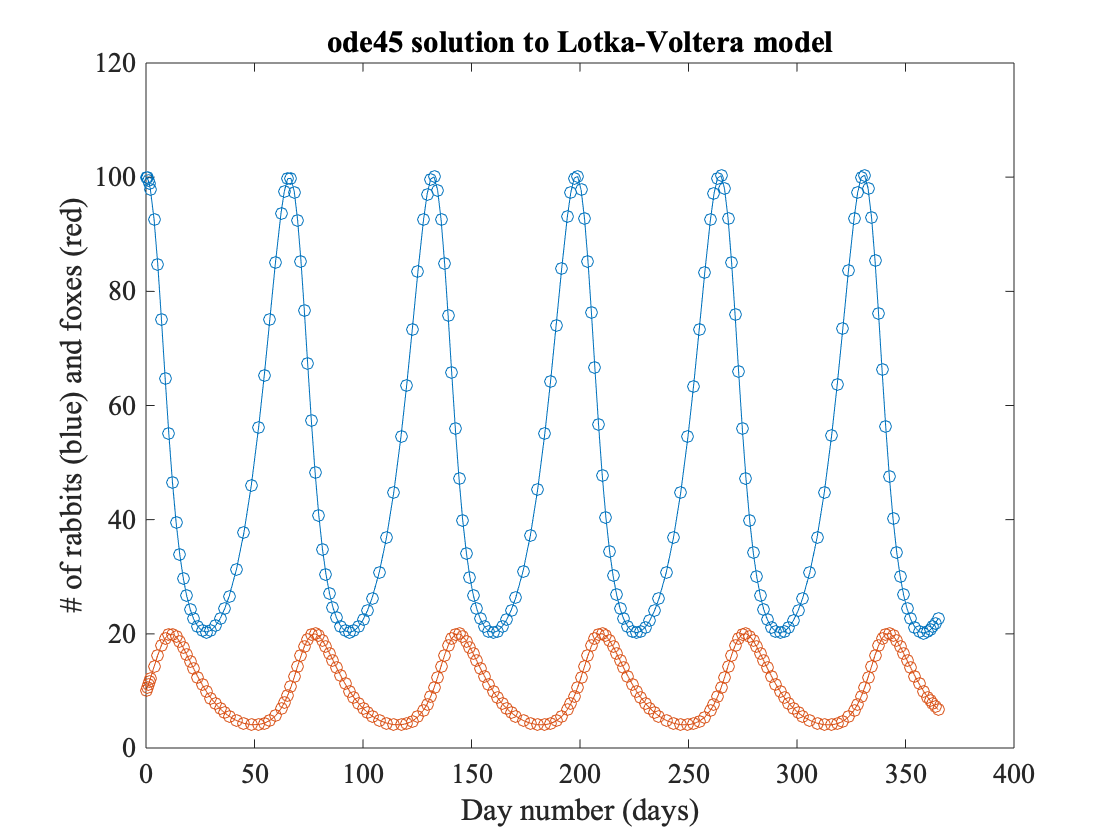

xlabel('Day number (days)')
ylabel('# of rabbits (blue) and foxes (red)')
title('ode45 solution to Lotka-Voltera model')

**Try this**: Check out the plot and try playing with initial conditions and model parameters. This is an extremely interesting nonlinear model without an analytic solution exhibiting a variety of behaviors including the oscillation indicated in the plot.

## Higher order differential equations as a system of equations with ode45.

`ode45` can handle a system (read collection) of 1st order equations. We can write F=ma in one dimension as a system of two equations for two variables $x$ and $v$ both of which depend upon each other and upon an independent variable t. The general form is: 


$$dv/dt = A(z,v,t)$$
 

$dx/dt = B(z,v,t)== v$. 

The 2nd equation in this instance is quite simple. For a general system of two first order equations, $A$ and $B$ are both aribtrary functions.You can modify this vectorized version of `ode45` to solve any F=ma problem with forces of known dependence upon position and velocity and time. Use a 6-vector `V` of 3 velocity plus 3 coordinate functions of time. The rate of change `dV/dt` of this 6-vector V can be written as a column of 6 functions of velocity and position components and time. Code the rates of change in a function called, say, V_t`(t, V)` like lotka and call `ode45` like 

`[Tode, Vode]=ode45(@V_t,[tmin,tmax],V0) `

with `V0` a column of initial velocity components and position coordinates, and V_t the name of a function that computes rates of change. 

**Appendix 1**

Here is our rate of change function for ballistics with drag linear in velocity. It must be placed at the end of the Live Script  or placed as a separate file in the MATLAB path with the filename equal to the name of the function (e.g. accel.m) where MATLAB can find it by filename. It uses the global parameters values (g and tau) and the input independent variable value for time tx (not needed for a force with no explicit time dependence) and the  dependent variable value vx at that time to compute and return the acceleration. The variable to be returned is defined to be a by the equals sign in the function declaration. that value is computed just before the function ends.

To create a function, we use the MATLAB [function](https://www.mathworks.com/help/matlab/ref/function.html) declaration. The local (to the function) variable `a` is the quantity returned by the function and calculated in the function.

function a=v_t(tx,vx)
    global g; % acceleration of gravity in m-s^-2
    global tau; %drag time in s
    a = g- (vx/tau);
end

**Appendix 2**

Here is the lotka rate function used for the population model.

function rate = lotka(t, V)
    % unpack the elements of V
    r = V(1);
    f = V(2);
    % set the parameters
    a = 0.1;
    b = 0.01;
    c = 0.1;
    e = 0.2;
    % compute the derivatives
    drdt = a*r - b*r*f;
    dfdt = e*b*r*f - c*f;
    % pack the derivatives into a vector
    rate = [drdt; dfdt];
end

## End of script